DRS converged in 19 iterations.
DRS converged in 18 iterations.
DRS converged in 18 iterations.
DRS converged in 18 iterations.
DRS converged in 18 iterations.
DRS converged in 18 iterations.
DRS converged in 18 iterations.
DRS converged in 18 iterations.
DRS converged in 17 iterations.
DRS converged in 17 iterations.
DRS converged in 17 iterations.
DRS converged in 17 iterations.
DRS converged in 17 iterations.
DRS converged in 17 iterations.
DRS converged in 17 iterations.
DRS converged in 16 iterations.
DRS converged in 16 iterations.
DRS converged in 16 iterations.
DRS converged in 16 iterations.
DRS converged in 15 iterations.
DRS converged in 15 iterations.
DRS converged in 15 iterations.
DRS converged in 14 iterations.
DRS converged in 14 iterations.
DRS converged in 15 iterations.
DRS converged in 17 iterations.
DRS converged in 17 iterations.
DRS converged in 16 iterations.
DRS converged in 16 iterations.
DRS converged in 16 iterations.
DRS converged in 16 iterations.
DRS conv

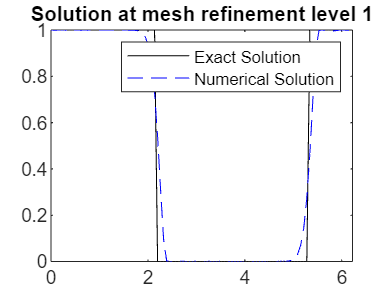

DRS converged in 19 iterations.
DRS converged in 18 iterations.
DRS converged in 18 iterations.
DRS converged in 18 iterations.
DRS converged in 18 iterations.
DRS converged in 18 iterations.
DRS converged in 18 iterations.
DRS converged in 18 iterations.
DRS converged in 17 iterations.
DRS converged in 17 iterations.
DRS converged in 17 iterations.
DRS converged in 17 iterations.
DRS converged in 17 iterations.
DRS converged in 17 iterations.
DRS converged in 17 iterations.
DRS converged in 16 iterations.
DRS converged in 16 iterations.
DRS converged in 16 iterations.
DRS converged in 16 iterations.
DRS converged in 15 iterations.
DRS converged in 15 iterations.
DRS converged in 15 iterations.
DRS converged in 14 iterations.
DRS converged in 14 iterations.
DRS converged in 16 iterations.
DRS converged in 17 iterations.
DRS converged in 17 iterations.
DRS converged in 16 iterations.
DRS converged in 16 iterations.
DRS converged in 16 iterations.
DRS converged in 16 iterations.
DRS conv

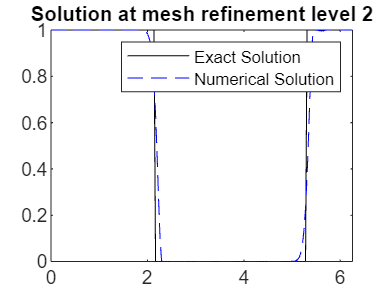

DRS converged in 19 iterations.
DRS converged in 18 iterations.
DRS converged in 18 iterations.
DRS converged in 18 iterations.
DRS converged in 18 iterations.
DRS converged in 18 iterations.
DRS converged in 18 iterations.
DRS converged in 18 iterations.
DRS converged in 17 iterations.
DRS converged in 17 iterations.
DRS converged in 17 iterations.
DRS converged in 17 iterations.
DRS converged in 17 iterations.
DRS converged in 17 iterations.
DRS converged in 17 iterations.
DRS converged in 16 iterations.
DRS converged in 16 iterations.
DRS converged in 16 iterations.
DRS converged in 16 iterations.
DRS converged in 15 iterations.
DRS converged in 15 iterations.
DRS converged in 15 iterations.
DRS converged in 14 iterations.
DRS converged in 14 iterations.
DRS converged in 16 iterations.
DRS converged in 17 iterations.
DRS converged in 17 iterations.
DRS converged in 16 iterations.
DRS converged in 16 iterations.
DRS converged in 16 iterations.
DRS converged in 16 iterations.
DRS conv

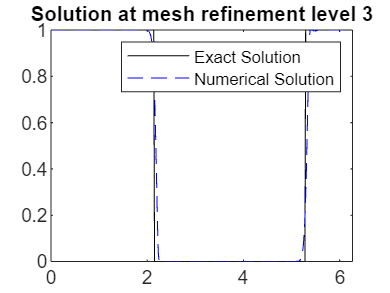

DRS converged in 19 iterations.
DRS converged in 18 iterations.
DRS converged in 18 iterations.
DRS converged in 18 iterations.
DRS converged in 18 iterations.
DRS converged in 18 iterations.
DRS converged in 18 iterations.
DRS converged in 18 iterations.
DRS converged in 17 iterations.
DRS converged in 17 iterations.
DRS converged in 17 iterations.
DRS converged in 17 iterations.
DRS converged in 17 iterations.
DRS converged in 17 iterations.
DRS converged in 17 iterations.
DRS converged in 16 iterations.
DRS converged in 16 iterations.
DRS converged in 16 iterations.
DRS converged in 16 iterations.
DRS converged in 15 iterations.
DRS converged in 15 iterations.
DRS converged in 15 iterations.
DRS converged in 14 iterations.
DRS converged in 14 iterations.
DRS converged in 16 iterations.
DRS converged in 17 iterations.
DRS converged in 17 iterations.
DRS converged in 16 iterations.
DRS converged in 16 iterations.
DRS converged in 16 iterations.
DRS converged in 16 iterations.
DRS conv

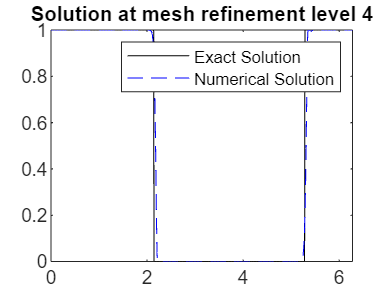

DRS converged in 19 iterations.
DRS converged in 18 iterations.
DRS converged in 18 iterations.
DRS converged in 18 iterations.
DRS converged in 18 iterations.
DRS converged in 18 iterations.
DRS converged in 18 iterations.
DRS converged in 18 iterations.
DRS converged in 17 iterations.
DRS converged in 17 iterations.
DRS converged in 17 iterations.
DRS converged in 17 iterations.
DRS converged in 17 iterations.
DRS converged in 17 iterations.
DRS converged in 17 iterations.
DRS converged in 16 iterations.
DRS converged in 16 iterations.
DRS converged in 16 iterations.
DRS converged in 16 iterations.
DRS converged in 15 iterations.
DRS converged in 15 iterations.
DRS converged in 15 iterations.
DRS converged in 14 iterations.
DRS converged in 14 iterations.
DRS converged in 16 iterations.
DRS converged in 17 iterations.
DRS converged in 17 iterations.
DRS converged in 16 iterations.
DRS converged in 16 iterations.
DRS converged in 16 iterations.
DRS converged in 16 iterations.
DRS conv

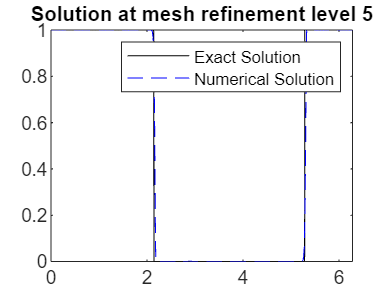

% Sanaz Hami
% Integrating DR Function into 1D Linear Advection with Periodic IC

% Initialization of parameters
xa = 0;
xb = 2 * pi;
T = 1;
lambda_DR = 0.5; % Relaxation parameter for DR
epsilon = 1e-6; % Convergence criterion for DR
max_iter = 1000; % Maximum iterations for DR
m = 0; % Define lower bound for DR
M = 1; % Define upper bound for DR
v0 = @(x) double(mod(x, 2*pi) < pi); % New initial condition
errtab = zeros(5, 2);

% Main loop for mesh refinement
for kk = 1:5
    Nx = 100 * (2 ^ (kk - 1)) - 1;
    h = (xb - xa) / (Nx + 1);
    lambda = 0.1; 
    k = lambda * h; % Updated time step calculation
    %k = h^2;
    v = zeros(1, Nx + 3);
    x = linspace(xa, xb - h, Nx + 1);
    v(2:Nx + 2) = v0(x);
    v(1) = v(Nx + 2);
    v(Nx + 3) = v(2);

    % Time marching
    for ii = 1:floor(T / k)
        v_new = zeros(size(v));
        for jj = 2:Nx + 2
            v_new(jj) = v(jj) + ((k / h) / 2) * (v(jj + 1) - v(jj - 1));
        end
        v_new(1) = v_new(Nx + 2);
        v_new(Nx + 3) = v_new(2);
        v = v_new;

        % Call DR function after each time step
        u_guess = v(2:Nx+2); % Use the current solution as the initial guess
        v(2:Nx+2) = DR(m, M, v(2:Nx+2), u_guess, epsilon, max_iter, lambda_DR); % Post-process the solution
    end

    % Calculate numerical error and plot
    u_exac = v0(x + T);
    errtab(kk, 1) = sqrt(sum((u_exac - v(2:Nx + 2)).^2 * h));
    figure; % Create a new figure for each plot
    plot(x, u_exac, 'k-', x, v(2:Nx + 2), 'b--');
    legend('Exact Solution', 'Numerical Solution');
    title(sprintf('Solution at mesh refinement level %d', kk));
    drawnow; % Update the plot
end


% Compute the order of accuracy
for kk = 2:5
    errtab(kk, 2) = log(errtab(kk - 1, 1) / errtab(kk, 1)) / log(2);
end

format shortE;
disp(errtab) % Display the error table

   2.4761e-01            0
   2.2083e-01   1.6513e-01
   1.9980e-01   1.4440e-01
   1.9596e-01   2.7958e-02
   1.5028e-01   3.8295e-01




% DR function

function [u_mod] = DR(m, M, u, u_guess, epsilon, max_iter, lambda)
    N = length(u); % Number of elements in u
    b = sum(u); % Sum of u, which should be preserved
    c = b / N; % Average of the elements in u

    % Initialize the modified solution with the initial guess
    u_mod = u_guess;
    
    % Auxiliary variables for the DRS method
    y = u_mod; % Initialization of the auxiliary variable y
    z = zeros(size(u_mod)); % Initialization of the auxiliary variable z

    for iter = 1:max_iter
        % Step 1: Reflection
        y_reflected = 2 * u_mod - y;
        
        % Projection onto the set [m, M]
        z = min(max(y_reflected, m), M);
        
        % Step 2: Reflection
        z_reflected = 2 * z - y_reflected;
        
        % Projection onto the hyperplane {x | sum(x) = b}
        y = z_reflected + (b - sum(z_reflected)) / N;
        
        % Check for convergence: if the norm is less than epsilon, stop
        if norm(y - u_mod, 2) <= epsilon
            disp(['DRS converged in ', num2str(iter), ' iterations.']);
            break;
        end
        
        % Update for the next iteration
        u_mod = (1 - lambda) * u_mod + lambda * y;
    end

    if iter == max_iter
        warning('DRS did not converge within the maximum number of iterations.');
        u_mod = u_guess; % If not converged, return the initial guess
    end

    % The last step ensures that the sum of u_mod equals the sum of the original u

    % Adjust u_mod to satisfy the conservation property
    u_mod = u_mod + (b - sum(u_mod)) / N;
end